\Teste do NEulerSED com o problema da mola massa sem amortecimento

syms u(t) v(t)

f =@(t,u,v) v

f = function_handle with value:
    @(t,u,v)v


g =@(t,u,v) -16*u

g = function_handle with value:
    @(t,u,v)-16*u



a = 0

a = 0

b = 8

b = 8

n = 100

n = 100

u0 = 9

u0 = 9

v0 = 0

v0 = 0


SED = [diff(u,t)==f(t,u,v), diff(v,t)==g(t,u,v)]

$$SED(t) = \left(\begin{array}{cc} \frac{\partial }{\partial t}u\left(t\right)=v\left(t\right) & \frac{\partial }{\partial t}v\left(t\right)=-16\,u\left(t\right) \end{array}\right)$$

CI = [u(a)==u0, v(a)==v0]

$$CI = \left(\begin{array}{cc} u\left(0\right)=9 & v\left(0\right)=0 \end{array}\right)$$

 
[uExata, vExata] = dsolve(SED,CI)

$$uExata = 9\,\cos\left(4\,t\right)$$

$$vExata = -36\,\sin\left(4\,t\right)$$

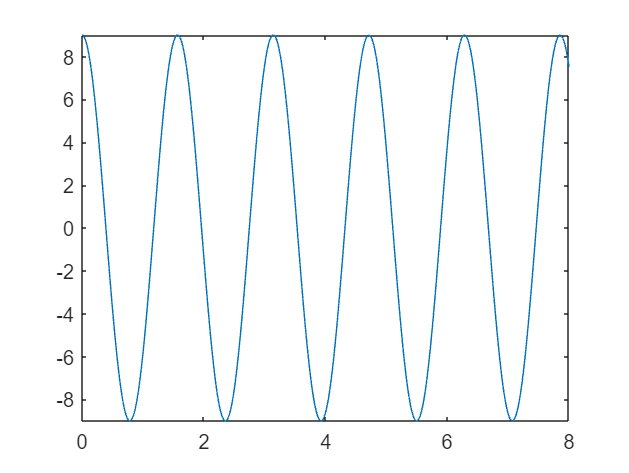

fplot(uExata, [a,b])



[t,u,v] = NEulerSED(f,g,a,b,n,u0,v0);

A = [t.',u.',v.'];
tabelaResultados = array2table(A,"VariableNames",["t","u","v"])

tabelaResultados = 101×3 table
     t         u          v   
    ____    _______    _______

       0          9          0
    0.08          9     -11.52
    0.16     8.0784     -23.04
    0.24     6.2352     -33.38
    0.32     3.5648    -41.361
     0.4    0.25586    -45.924
    0.48    -3.4181    -46.252
    0.56    -7.1182    -41.877
    0.64    -10.468    -32.765
    0.72     -13.09    -19.366
     0.8    -14.639    -2.6111
    0.88    -14.848     16.127
    0.96    -13.558     35.132
    1.04    -10.747     52.485
    1.12    -6.5482     66.242
     1.2    -1.2489     74.623


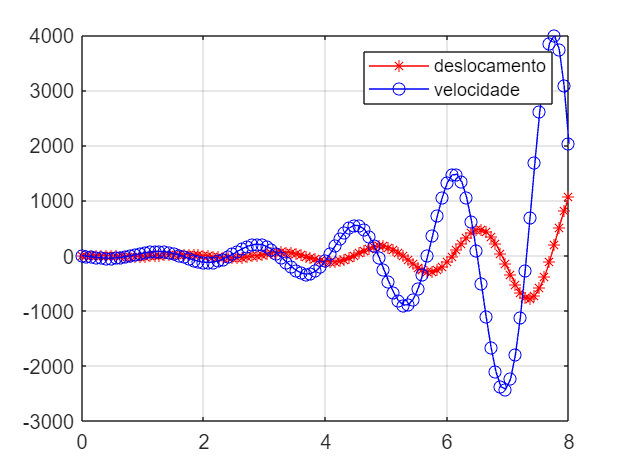


plot(t,u,"-r*")
hold on
plot(t,v,"-bo")
hold off
grid on
legend("deslocamento", "velocidade")


whos

  Name                    Size             Bytes  Class              Attributes

  A                     101x3               2424  double                       
  CI                      1x2                  8  sym                          
  SED                     1x1                  8  symfun                       
  a                       1x1                  8  double                       
  b                       1x1                  8  double                       
  ci                      1x2                  8  sym                          
  dt                      1x1                  8  double                       
  erroEuler               1x101                8  sym                          
  f                       1x1                 32  function_handle              
  g                       1x1                 32  function_handle              
  h                       1x1                 32  function_handle              
  i                       1x1          